**Stereo Camera Calibration**

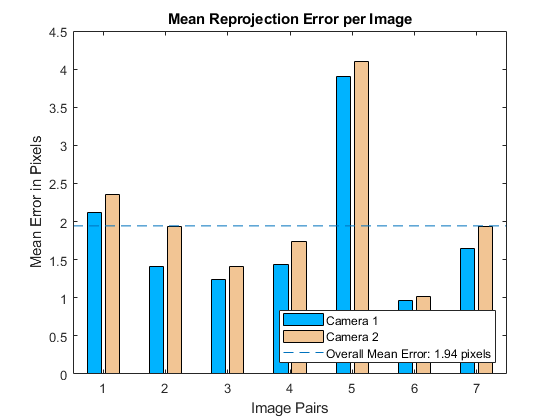

% Define images to process
imageFileNames1 = {'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000000.T000.D000.P000.H000.LA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000006.T000.D000.P000.H000.LA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000009.T000.D000.P000.H000.LA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000011.T000.D000.P000.H000.LA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000012.T000.D000.P000.H000.LA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000013.T000.D000.P000.H000.LA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Left\cali000014.T000.D000.P000.H000.LA.TIF',...
    };
imageFileNames2 = {'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000000.T000.D000.P000.H000.RA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000006.T000.D000.P000.H000.RA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000009.T000.D000.P000.H000.RA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000011.T000.D000.P000.H000.RA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000012.T000.D000.P000.H000.RA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000013.T000.D000.P000.H000.RA.TIF',...
    'C:\Users\liuhong2\Desktop\Leaf_DIC\DIC_cali\Right\cali000014.T000.D000.P000.H000.RA.TIF',...
    };

% Detect checkerboards in images
[imagePoints, boardSize, imagesUsed] = detectCheckerboardPoints(imageFileNames1, imageFileNames2);

% Generate world coordinates of the checkerboard keypoints
squareSize = 2.250000e+01;  % in units of 'millimeters'
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Read one of the images from the first stereo pair
I1 = imread(imageFileNames1{1});
[mrows, ncols, ~] = size(I1);

% Calibrate the camera
[stereoParams, pairsUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', true, 'EstimateTangentialDistortion', true, ...
    'NumRadialDistortionCoefficients', 3, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(stereoParams);

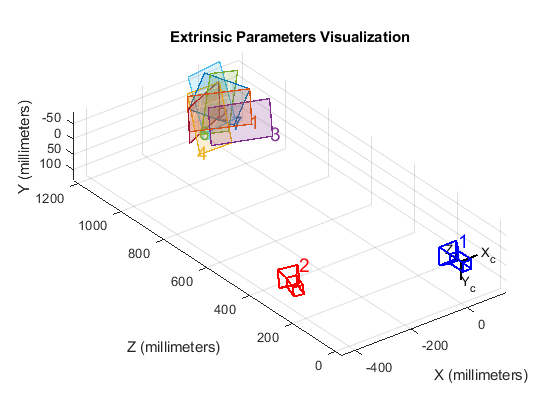


% Visualize pattern locations
h2=figure; showExtrinsics(stereoParams, 'CameraCentric');


% Display parameter estimation errors
displayErrors(estimationErrors, stereoParams);


			Standard Errors of Estimated Stereo Camera Parameters
			-----------------------------------------------------

Camera 1 Intrinsics
-------------------
Focal length (pixels):   [ 6686.2818 +/- 69.5716    6665.5808 +/- 68.9224 ]
Principal point (pixels):[ 1130.4269 +/- 56.1638     619.8362 +/- 65.5169 ]
Skew:                    [    4.4319 +/- 5.8279  ]
Radial distortion:       [   -0.6666 +/- 0.3122       71.5021 +/- 33.4597  -1769.1658 +/- 1007.0811]
Tangential distortion:   [   -0.0009 +/- 0.0044       -0.0128 +/- 0.0043  ]

Camera 1 Extrinsics
-------------------
Rotation vectors:
                         [    0.7473 +/- 0.0130        0.1086 +/- 0.0154        3.0224 +/- 0.0043  ]
                         [   -0.6539 +/- 0.0131        0.0601 +/- 0.0152        3.0755 +/- 0.0038  ]
                         [   -0.6209 +/- 0.0132       -0.3398 +/- 0.0158       -3.0425 +/- 0.0035  ]
                         [   -0.2928 +/- 0.0113       -0.2516 +/- 0.0092       -1.5452 +/- 0.0020  ]
 


% You can use the calibration data to rectify stereo images.
I2 = imread(imageFileNames2{1});
%[J1, J2] = rectifyStereoImages(I1, I2, stereoParams);

% See additional examples of how to use the calibration data.  At the prompt type:
% showdemo('StereoCalibrationAndSceneReconstructionExample')
% showdemo('DepthEstimationFromStereoVideoExample')

**Triangulation**

testIndex = 2

testIndex = 2

fileNames = dir('left*.mat');
LeftNames = extractfield(fileNames,'name')

LeftNames = 1×2 cell array
    {'left_centroid_8_spike.mat'}    {'left_centroid_8_split.mat'}


fileNames = dir('right*.mat');
RightNames = extractfield(fileNames,'name')

RightNames = 1×2 cell array
    {'right_centroid_8_spike.mat'}    {'right_centroid_8_split.mat'}


%fprintf(LeftNames{testIndex}); caseLeft = split(LeftNames{testIndex},'.mat'); caseLeft = caseLeft{1};
%fprintf(RightNames{testIndex}); caseRight = split(RightNames{testIndex}, '.mat'); caseRight = caseRight{1};
LeftData = load(LeftNames{testIndex}); RightData = load(RightNames{testIndex});
fprintf(LeftNames{testIndex});

left_centroid_8_split.mat

LeftData = struct2cell(LeftData);RightData = struct2cell(RightData);
LC = LeftData{1}; LL = LeftData{2}; % Left Center and label
RC = RightData{1}; RL = RightData{2}; % Right Center and label

Points = {};
[N, t, ~] = size(LC);

for i = 1:t
    Lpoints = squeeze(LC(:,i,:));
    Lpoints_undistort = undistortPoints(Lpoints, stereoParams.CameraParameters1);
    %Lpoints_undistort = Lpoints;
    Lpoints_undistort = Lpoints_undistort(LL,:);
    
    
    Rpoints = squeeze(RC(:,i,:));
    Rpoints_undistort = undistortPoints(Rpoints, stereoParams.CameraParameters2);
    %Rpoints_undistort = Rpoints;
    Rpoints_undistort = Rpoints_undistort(RL,:); % sort to match the points in Left
    
    
    
    worldPoints = triangulate(Lpoints_undistort, Rpoints_undistort, stereoParams);
    Points{i} = worldPoints;
    
end

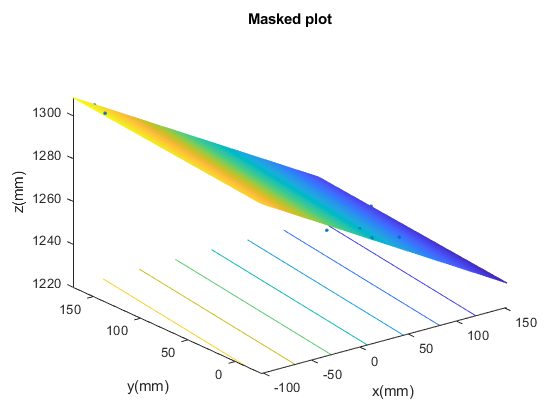

Lpoints_undistort = undistortPoints(left, stereoParams.CameraParameters1);
Rpoints_undistort = undistortPoints(right, stereoParams.CameraParameters2);


worldPoints = triangulate(Lpoints_undistort, Rpoints_undistort, stereoParams);
points = worldPoints;
figure()
plot3(points(:,1), points(:,2),points(:,3),'.');
x = points(:,1); y = points(:,2); z = points(:,3);
DM = [x, y, ones(size(z))];                             % Design Matrix
B = DM\z;  
[X,Y] = meshgrid(linspace(min(x),max(x),50), linspace(min(y),max(y),50));
Z = B(1)*X + B(2)*Y + B(3)*ones(size(X));
hold on
meshc(X, Y, Z)
hold off
xlabel('x(mm)'); ylabel('y(mm)'); zlabel('z(mm)');
title('Masked plot');

fprintf('Z = %.3f\\cdotX %+.3f\\cdotY %+3.0f',B)

Z = -0.267\cdotX +0.045\cdotY +1273

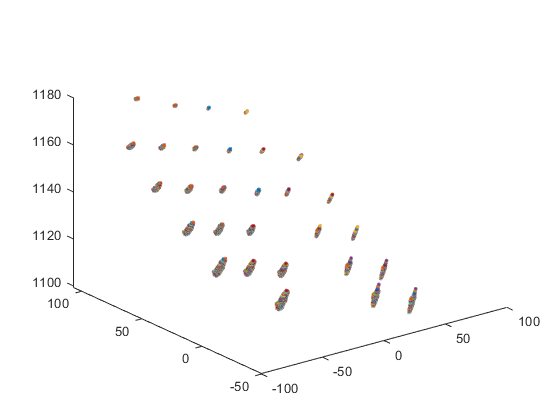

figure()
for i = 1:length(Points)
    points = Points{i};
    plot3(points(:,1), points(:,2),points(:,3),'.');
    hold on;
    
end